## Simulation that models how musical motor skills are retained or lost over a 30-day period based on different practice schedules

The simulation demonstrates that consistent daily practice leads to the highest proficiency levels for both simple piece  and compex piece the result is 100, regardless of task difficulty.

as seen in the weekend warrior model, results in continous skill decay due to insufficient reinforcement. The erratic learner exhibits moderate but unstable performance, highlighting the importance of regularity in practice schedules. increasing decay rate significantly impacts irregular learners, while consistent practice effectively mitigates the effect of faster forgetting. 

On changing reinforcement from 10 to 6, the graph shows, consistent student grows and it mitigates from early reaching 100. which means the student is growing slowly. At this point the result of complex piece become different from 100. 

Beisdes that when fatigue value(penality) decreases from 0.02 to 0.01 we can see the trend of weekend student that drop->spike a little->drop->spike a little.

And the erratic student has almost approximate performance on both simple and complex pieces. That means lower penality(fatigue=0.01) so the student is working good for long time. 

Sensetivity Analysis: changes

Low decay -> easier skill retention

High decay - > Faster Forgetting

So, practice frequency is more important than practice duration

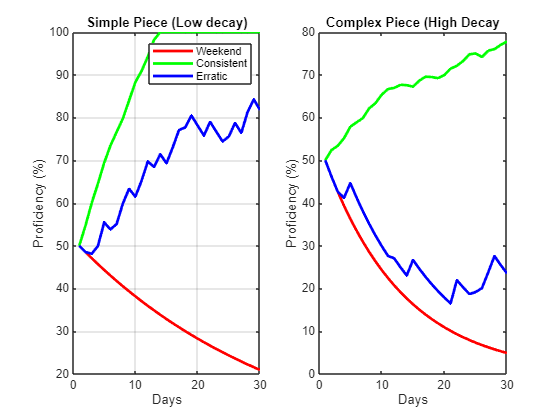

clear; clc;

%parameters

days = 30;
R= 6; 
lambda = 0.05;
fatigue = 0.02;

%sensetivity analysis( to check difficulty levels)

lambda_simple = 0.03;
lambda_complex = 0.08;

% run simulations : weekend practice(pw_s),consistent(pc_s), erratic(pe_s)
% for simple(s) and complex(c)

[pw_s, pc_s, pe_s] = run_simulation(lambda_simple, days,R, fatigue);
[pw_c, pc_c, pe_c] = run_simulation(lambda_complex, days,R, fatigue);

t = 1:days;

%%plot results

figure;
subplot(1,2,1)
plot(t,pw_s, 'r','LineWidth',2); hold on; % together
plot(t,pc_s, 'g','LineWidth',2);
plot(t,pe_s, 'b','LineWidth',2);

title('Simple Piece (Low decay)');
xlabel('Days');
ylabel('Proficiency (%)');
legend('Weekend', 'Consistent','Erratic');
grid on;

% Complex piece
subplot(1,2,2)
plot(t,pw_c, 'r','LineWidth',2); hold on;
plot(t,pc_c, 'g','LineWidth',2); hold on;
plot(t,pe_c, 'b','LineWidth',2); hold on;
title('Complex Piece (High Decay');
xlabel('Days');
ylabel('Proficiency (%)');


fprintf('*** Final Proficiency ***');

*** Final Proficiency ***

fprintf('\n ---SIMPLE PIECE ---\n');


 ---SIMPLE PIECE ---


fprintf('Weekend: %.2f\n', pw_s(end));

Weekend: 20.95


fprintf('Consistent: %.2f\n',pc_s(end));

Consistent: 100.00


fprintf('Erratic: %.2f\n',pe_s(end));

Erratic: 81.76



fprintf('\n --- COMPLEX PIECE ***');


 --- COMPLEX PIECE ***

fprintf('Weekend: %.2f\n', pw_c(end));

Weekend: 4.91


fprintf('Consistent: %.2f\n', pc_c(end));

Consistent: 77.80


fprintf('Erratic: %.2f\n', pe_c(end));

Erratic: 23.52


## Export CSV

T = table((1:days)', pw_s',pc_s', pe_s', ...
    'VariableNames',{'Day','Weekend','Consistent','Erratic'});
writetable(T, 'simulation_results_simple.csv');



function [p_weekend, p_consistent, p_erratic] = run_simulation(lambda, days, R, fatigue)


% Initialize arrays

p_weekend = zeros(1, days);
p_consistent = zeros(1, days);
p_erratic = zeros(1, days);

% initialize proficiency

p_weekend(1) = 50;
p_consistent(1) = 50;
p_erratic(1) = 50;


for d = 2:days
    %% *********** weekend warrior *************
   %forgetting 

   p_weekend(d) = p_weekend(d-1) *exp(-lambda);

   if mod(d,7) == 6 % e.g saturday
       duration = 120;
   else
       duration = 0; % no practice
   end
   

   %both weekend days
   % if mod(d,7) == 6  || mod(d,7) == 0 % e.g saturday
   %     duration = 100;
   % else
   %     duration = 0; % no practice
   % end

   % fatigue

   if duration > 45
        efficiency = max(0, 1- fatigue*(duration - 45)); %efficiency can not be zero
   else
         efficiency = 1;
   end

    %randomness

    efficiency = efficiency * (0.8 + 0.4*rand);
    
   if duration > 0
        p_weekend(d) = p_weekend(d) + R *efficiency;
   end
   % cap at 100
   p_weekend(d) = min(100, p_weekend(d));

   %% *********** Consistent Student*************

   % Forgetting / decay

   p_consistent(d) = p_consistent(d-1)*exp(-lambda);

   % daily practice

   duration = 30;

   % Fatigue

    if duration > 45
        efficiency = max(0, 1- fatigue*(duration - 45)); %efficiency should not be zero
     else
         efficiency = 1;
    end

    efficiency = efficiency * (0.8 + 0.4*rand);

    if duration > 0
        p_consistent(d) = p_consistent(d) +R *efficiency;    % learning
    end
    p_consistent(d) = min(100, p_consistent(d));

    %% ***************** Erratic Learner ***********

    %forgetting

   p_erratic(d) = p_erratic(d-1) * exp(-lambda);

   %random practice

   if rand > 0.5
       duration = randi([20, 90]);
   else
       duration = 0;
   end
  
   % Fatigue

    if duration > 45
        efficiency = max(0, 1- fatigue*(duration - 45));    %efficiency should not be zero
     else
         efficiency = 1;
    end

    efficiency = efficiency * (0.8 + 0.4*rand);

    if duration > 0
        p_erratic(d) = p_erratic(d) + R *efficiency;    % learning
    end
    p_erratic(d) = min(100, p_erratic(d));

end
end



